## `PS2`

`刘沛雨 2100012289 信息科学技术学院`

`本次作业由个人独立完成`

### Lab Manual

#### ﻿**Exercise 7.1**

**﻿**Modify Parasite1.m so that there is random variation in parasite success, depending on whether or not conditions on a given day are stressful. Specifically, on bad days" the parasites increase by 10% while on good days" they are beaten down by your immune system and they go down by 10%, and similarly for your assistant. That is,

Bad days: $n\left(j+1\right)=1\ldotp 1n\left(j\right);\;m\left(j+1\right)=1\ldotp 2m\left(j\right)$

Good days: $n\left(j+1\right)=0\ldotp 9n\left(j\right);m\left(j\right)=0\ldotp 8m\left(j\right)$

Do this by using rand(1) and an if statement to "toss a coin" each day: if the random value produced by rand for that day is < 0.35 it’s a good day, and otherwise it’s bad.

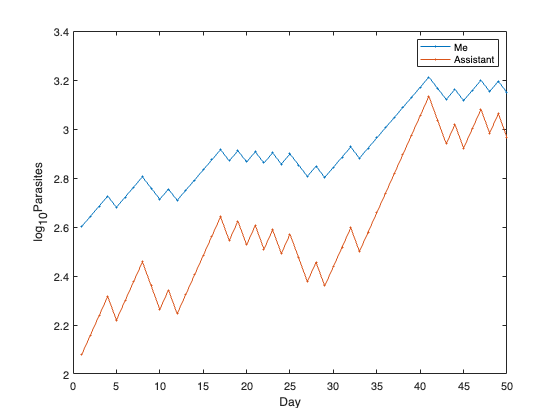

% modified parasite1
time_range =50;
time_vector = 1:time_range;
parasites = zeros(2, time_range);
parasites(1, 1) = 400; % me
parasites(2, 1) = 120; % assistant
me_rate = 0.1;
assistant_rate = 0.2;
for t = 2: time_range
    if rand(1) < 0.35 % a good day
        parasites(1, t) = parasites(1, t - 1) * (1 - me_rate);
        parasites(2, t) = parasites(2, t - 1) * (1 - assistant_rate);
    else % a bad day
        parasites(1, t) = parasites(1, t - 1) * (1 + me_rate);
        parasites(2, t) = parasites(2, t - 1) * (1 + assistant_rate);
    end
end
% plot
for i = 1:size(parasites, 1)
    plot(time_vector, log10(parasites(i, :)), ' - .');
    hold on
end
legend(["Me", "Assistant"])
xlabel("Day")
ylabel("log_{10}Parasites")
hold off

### Logistic Map﻿

In this exercise, let’s examine the **period-doubling scenario** studied by Feigenbaum (as I illustrated in class). You may use the programs posted on the class website or your own. 

Chaos is often associated with nonlinear dynamics of a certain kind. We already saw in class how the simple logistic map can lead to complicated dynamics. The study of dynamics systems usually focus on the **behavior at long times** (especially, steady states and other “attractors”). We can study the onset of chaos in the logistic map as we change the value of a system parameter. 

When set in certain parameter regimes the logistic map provided us with an example where the dynamics can be “unpredictable.” In this exercise we will study the dynamics of the logistic map by looking at its behavior at long times where the solution (or trajectory) moves along attractors. (See, for instance, a period-4 attractor in the figure below.) In particular, we can study the onset of “chaotic” behavior by looking at changing the parameter $r$.


$$x_{n+1} =rx_n \left(1-x_n \right)$$


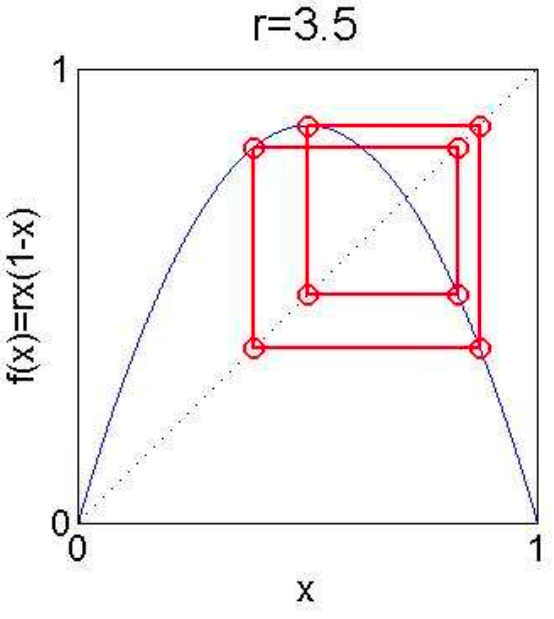﻿

(a) For $r=0\ldotp 75$, iterate the map for a few initial conditions $x_0$. Eventually, all solutions should go to zero (fixed point). Plot $f\left(x\right)=r\cdot x\left(1-x\right)\;\textrm{vs}\ldotp x$ and the diagonal $y=x$ **on the same plot**. Then write a short program to “cobweb” as I did on the blackboard during lecture. By iterating the logistic map many times, we can find points on the attractor. Find a value of $r$ so that the attractor has period 8. Hand in the figure (and label the value of $r$).

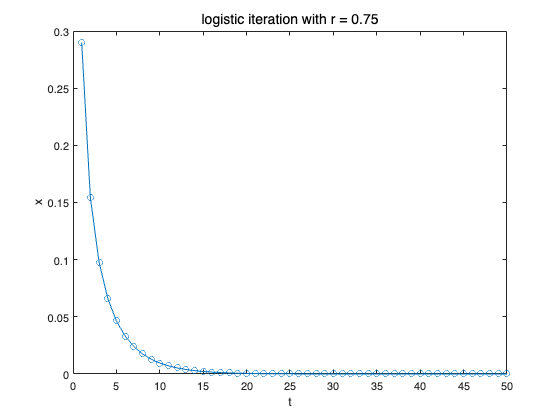

% r = 0.75, iterate the map for a few initial conditions x0
tmax = 50;
x0 = 0.29;
r = 0.75;
xt = logisticIteration(tmax, x0, r);
%plot
figure;
plot(xt, 'o-');
xlabel("t")
ylabel("x")
txt = ['logistic iteration with r = ', num2str(r)];
title(txt,'FontSize',14)

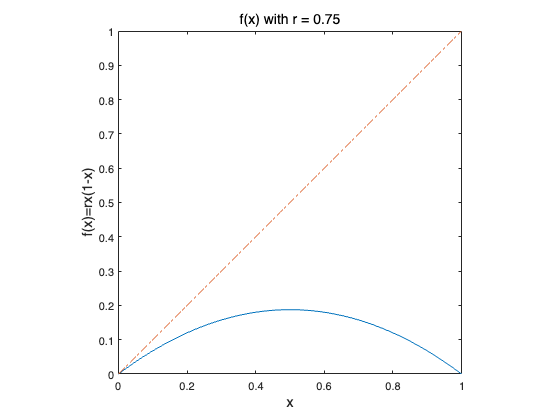

% plot f(x) and y = x
r =0.75;
x = 0: 0.0001: 1;
fx = logisticFunc(x, r);
% plot
figure;
plot(x, fx);
axis equal;axis([0 1 0 1]);
xlabel('x','FontSize', 14);
ylabel('f(x)=rx(1-x)', 'FontSize', 14);
hold on;
plot(x, x, '-.')
txt = ['f(x) with r = ', num2str(r)];
title(txt,'FontSize',14)

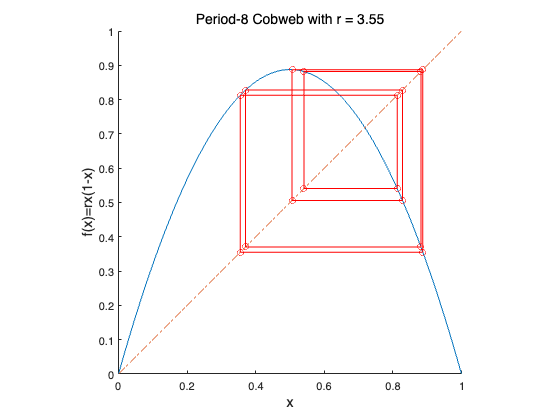

% cobweb plot
period = 8;
r =3.55;
x0 = 0.85;
max_iter = 75;
x = 0: 0.0001: 1;
fx = logisticFunc(x, r);
% iterate x_n
xn = zeros(max_iter, 1);
xn(1, 1) = x0;
for i = 2: max_iter
    xn(i, 1) = r * xn(i - 1, 1) * (1 - xn(i - 1, 1));
end
% plot
figure;
hold on;
plot(x, fx);
axis equal;
axis([0 1 0 1]);
xlabel('x','FontSize', 14);
ylabel('f(x)=rx(1-x)', 'FontSize', 14);
hold on;
plot(x, x, '-.')
plot(x)
hold on;
for i = max_iter - period: max_iter - 1
    plot([xn(i), xn(i)], [xn(i), xn(i + 1)], ['r', 'o-']);
    plot([xn(i), xn(i + 1)], [xn(i + 1), xn(i + 1)], ['r', 'o-']);
end
title("Period-8 Cobweb with r = 3.55", "FontSize", 14)

﻿﻿(b) As we saw in class, for $r>3$, the steady state solution $x^* =1-\frac{1}{r}$ is no longer stable. This can be shown by showing that the derivative $|f^{\prime } \left(x^* \right)|>1$.

证明：$x^*$为函数的不动点$\Leftrightarrow$$x^* =f\left(x^* \right)$. 考虑不动点$x^*$的局部稳定性.

设


$$f\left(x^* +\eta_n \right)=x^* +\eta_{n+1}$$


则

$x^* +\eta_{n+1} =f\left(x^* \right)+f^{\prime } \left(x^* \right)\eta_n +O\left(\eta_n^2 \right)=x^* +f^{\prime } \left(x^* \right)\eta_n +O\left(\eta_n^2 \right)\Rightarrow \eta_{n+1} \approx f^{\prime } \left(x^* \right)\eta_n$. 

令


$$\lambda =f^{\prime } \left(x^* \right)$$


则有


$$\eta_n =\lambda^n \eta_0$$


故


$$|\lambda |<1\Rightarrow \lim_{n\to \infty } \eta_n =0$$


即$x^*$是线性稳定（linearly stable）的$\Leftrightarrow {|f}^{\prime } \left(x^* \right)|<1$.

故当${|f}^{\prime } \left(x^* \right)|>1$时，$x^*$不是线性稳定的；而当${|f}^{\prime } \left(x^* \right)|=1$时（临界情况），$x^*$是否稳定由小量$O\left(\eta_n^2 \right)$决定.

证毕.

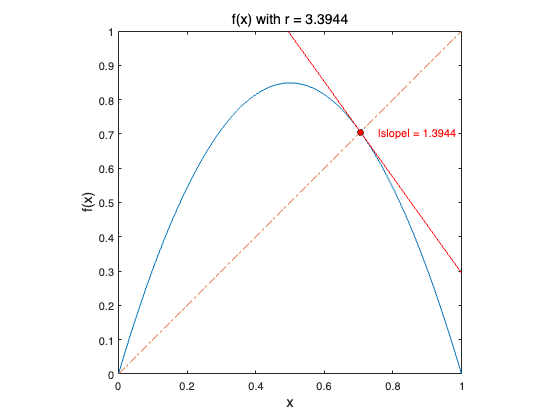

r = 3.3944;
x = 0: 0.0001: 1;
fx = logisticFunc(x, r);
x_star = 1 - 1 / r;
y_star = r * x_star * (1 - x_star);
slope = r - 2 * r * x_star;
tangent_line = @(x) slope*(x - x_star) + y_star;

% plot
figure;
plot(x, fx);
axis equal;axis([0 1 0 1]);
xlabel('x','FontSize',14);
ylabel('f(x)', 'FontSize', 14);
hold on;
plot(x, x, '-.')
plot(x, tangent_line(x), 'r-');
plot(x_star, y_star, 'ko', 'MarkerFaceColor', 'r');
txt = ['|slope| = ', num2str(abs(slope))];
text(x_star+0.05, y_star, txt, 'FontSize', 11, 'Color', 'r');
txt = ['f(x) with r = ', num2str(r)];
title(txt,'FontSize',14)

**Optional exercise:** By looking at the second iteration of the map and examining the fixed points of $x=f\left(f\left(x\right)\right)$ .Show that the period 2 solution is stable for $3<r<1+\sqrt{6}$.

证明：计算二阶不动点$p,q$以及$f\left(f\left(x\right)\right)$在$p,q$处的切线斜率的过程如下：

$p,q$满足方程$f\left(f\left(x\right)\right)=x$.

化简得:


$$x=r^2 x\left(1-r\right)\left(1-\lambda r\left(1-r\right)\right)$$



$$x\left(x-\frac{r-1}{r}\right)\left(x^2 -\frac{r+1}{r}x+\frac{r+1}{r^2 }\right)=0$$


注意到$x=0$和$x=\frac{r-1}{r}$为两个一阶不动点，故真正的二周期解为：


$$p=\frac{1}{2}\left(\frac{1+r}{r}+\frac{\sqrt{\left(r+1\right)\left(r-3\right)}}{r}\right),\;q=\frac{1}{2}\left(\frac{1+r}{r}-\frac{\sqrt{\left(r+1\right)\left(r-3\right)}}{r}\right)$$


当$r>3$时以上两实数解存在.

稳定性分析：


$$\frac{\mathrm{d}}{\mathrm{d}x}f\left(f\left(x\right)\right)=f^{\prime } \left(f\left(x\right)\right)f^{\prime } \left(x\right)$$


故


$$\frac{\mathrm{d}}{\mathrm{d}x}f\left(f\left(p\right)\right)=f^{\prime } \left(f\left(p\right)\right)f^{\prime } \left(p\right)=f^{\prime } \left(p\right)f^{\prime } \left(q\right)$$


由对称性知：


$$\frac{\mathrm{d}}{\mathrm{d}x}f\left(f\left(p\right)\right)=\frac{\mathrm{d}}{\mathrm{d}x}f\left(f\left(q\right)\right)=f^{\prime } \left(p\right)f^{\prime } \left(q\right)=r^2 \left(1-2p\right)\left(1-2q\right)=r^2 \left(1-2\left(p+q\right)+4p\cdot q\right)=-{\left(r-1\right)}^2 +5$$


令$|-{\left(r-1\right)}^2 +5|<1$得：


$$3<r<1+\sqrt{6}$$


证毕.

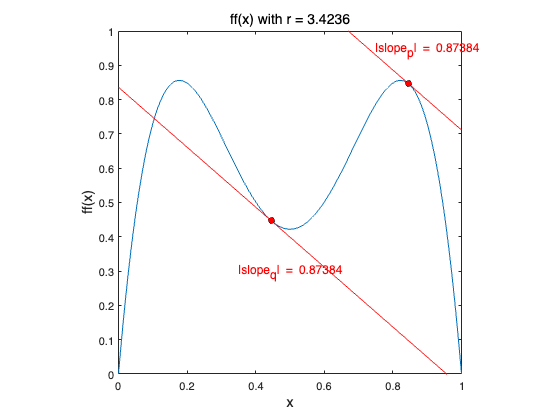

r = 3.4236; % 3 < r < 1+sqrt(6)
x = 0: 0.0001: 1;
ffx = logisticFunc(logisticFunc(x,r), r);
p = ((r + 1) + sqrt((r - 3) * (r + 1))) / (2 * r);
q = ((r + 1) - sqrt((r - 3) * (r + 1))) / (2 * r);
fp = r * (r * p * (1 - p)) * (1 - r * p * (1 - p));
fq = r * (r * q * (1 - q)) * (1 - r * q * (1 - q));
slope = 4 + 2 * r - r * r;  % df(f(x)) / dx (x = p)
tangent_line_p = @(x) slope*(x - p) + fp;
tangent_line_q = @(x) slope*(x - q) + fq;

% plot
figure;
plot(x, ffx);
axis equal;axis([0 1 0 1]);
xlabel('x','FontSize',14);
ylabel('ff(x)', 'FontSize', 14);
hold on;
plot(x, tangent_line_p(x), 'r-');
plot(p, fp, 'ko', 'MarkerFaceColor', 'r');
txt = ['|slope_p| = ', num2str(abs(slope))];
text(p-0.1, fp+0.1, txt, 'FontSize', 11, 'Color', 'r');
plot(x, tangent_line_q(x), 'r-');
plot(q, fq, 'ko', 'MarkerFaceColor', 'r');
txt = ['|slope_q| = ', num2str(abs(slope))];
text(q-0.1, fq-0.15, txt, 'FontSize', 11, 'Color', 'r');
txt = ['ff(x) with r = ', num2str(r)];
title(txt,'FontSize',14)

﻿(c) Let us try to construct the bifurcation diagram of the logistic map. Here the bifurcation diagram is a plot of the attractor as a function of $r$, for $0<r<4$. One way to do this is to pick regularly spaced $\delta r$ , run $n_{\textrm{transient}}$ steps, record $n_{\textrm{period}}$ steps and plot the recorded steps. Start with small $n_{\textrm{transient}}$ and $n_{\textrm{period}}$. After you make sure your matlab program is working, you may try for $\delta r<0\ldotp 01\;$and $n_{\textrm{transient}}$ and $n_{\textrm{period}} >100$. Make a figure and hand it in.

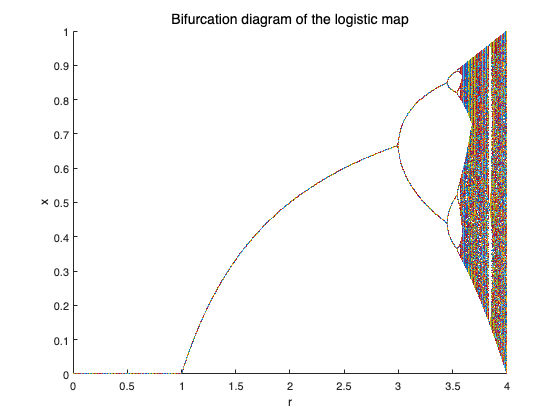

dr = 0.001;
rmin = 0;
rmax = 4;
rr = rmin:dr:rmax;
nr = length(rr);
ncmax = 200;
tmax = 500;
x0 = 0.5;
figure;
hold on;
for i=1:nr
    r = rr(i);
    xt = logisticIteration(tmax, x0, r);
    rs = r * ones(1, ncmax);
    plot(rs, xt(1, tmax - ncmax + 1: tmax), 'o', 'MarkerSize', 0.5);
end
ylabel('x');
xlabel('r');
title('Bifurcation diagram of the logistic map','FontSize',14)

Plot $f\left(f\left(x\right)\right)$ together with the diagonal $y=x$ for $r=3\ldotp 2$. Can you see that the period 2 solution of $f\left(x\right)$ becomes a pair of stable fixed points for $f\left(f\left(x\right)\right)$?

由下图可知，$f\left(x\right)$的二周期解$p,q$满足$f\left(f\left(p\right)\right)=p,f\left(f\left(q\right)\right)=q$.

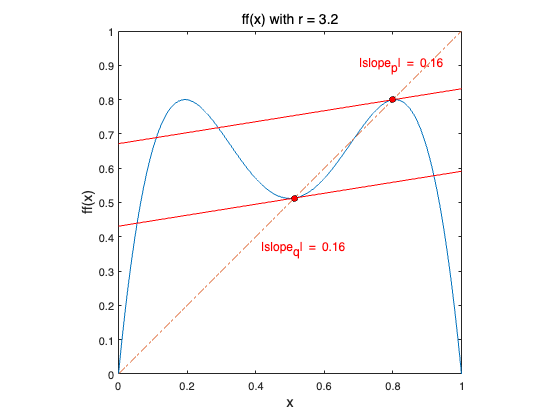

r = 3.2;
x = 0: 0.0001: 1;
ffx = logisticFunc(logisticFunc(x, r), r);
p = ((r + 1) + sqrt((r - 3) * (r + 1))) / (2 * r);
q = ((r + 1) - sqrt((r - 3) * (r + 1))) / (2 * r);
fp = r * (r * p * (1 - p)) * (1 - r * p * (1 - p));
fq = r * (r * q * (1 - q)) * (1 - r * q * (1 - q));
slope = 4 + 2 * r - r * r;  % df(f(x)) / dx (x = p)
tangent_line_p = @(x) slope*(x - p) + fp;
tangent_line_q = @(x) slope*(x - q) + fq;

% plot
figure;
plot(x, ffx);
axis equal;
axis([0 1 0 1]);
xlabel('x','FontSize',14);
ylabel('ff(x)', 'FontSize', 14);
hold on;
plot(x, x, '-.')
plot(x, tangent_line_p(x), 'r-');
plot(p, fp, 'ko', 'MarkerFaceColor', 'r');
txt = ['|slope_p| = ', num2str(abs(slope))];
text(p-0.1, fp+0.1, txt, 'FontSize', 11, 'Color', 'r');
plot(x, tangent_line_q(x), 'r-');
plot(q, fq, 'ko', 'MarkerFaceColor', 'r');
txt = ['|slope_q| = ', num2str(abs(slope))];
text(q-0.1, fq-0.15, txt, 'FontSize', 11, 'Color', 'r');
title('ff(x) with r = 3.2', 'FontSize', 14)

﻿Compare the plot with $f\left(x\right)$ for $r=2$. Notice that the region around $x=\frac{1}{2}$ for $f\left(f\left(x\right)\right)$ looks like an upside-down version of the map for $r=2$. Plot $f^{\left(4\right)} \left(x\right)$ for $r=3\ldotp 5$. Notice the similar map near $x=\frac{1}{2}$. The fact that the unimodal map reappears in scaled-down form after we change $r$ to get period doubling is the basic reason that each succeeding period-doubling follow one another. **Universality **comes from the fact that these unimodal maps have a shape that becomes independent of the original map after a few period-doubling bifurcations.

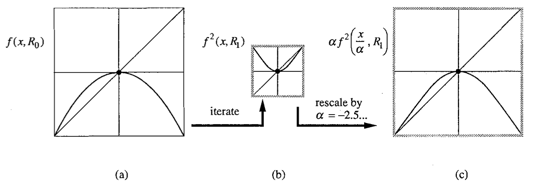

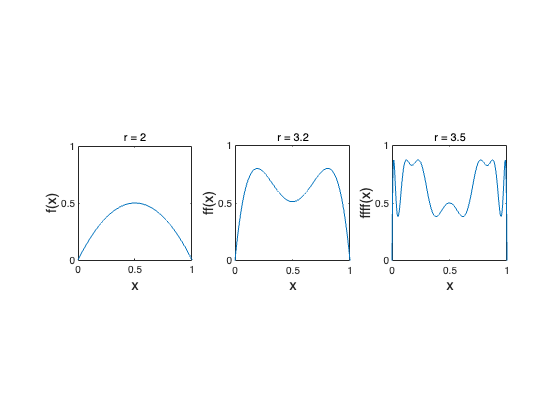

r = 2;
x = 0: 0.0001: 1;
fx = logisticFunc(x, r);
r = 3.5;
ffffx = logisticFunc(logisticFunc(logisticFunc(logisticFunc(x, r), r), r), r);
% plot
figure; subplot(1,3,1);
plot(x, fx);
title('r = 2')
axis equal;axis([0 1 0 1]);
xlabel('x','FontSize',14);
ylabel('f(x)', 'FontSize', 14);
hold on;
% plot(x, x, '-.')

subplot(1,3,2);
plot(x, ffx);
title('r = 3.2')
axis equal;axis([0 1 0 1]);
xlabel('x','FontSize',14);
ylabel('ff(x)', 'FontSize', 14);
hold on;
% plot(x, x, '-.')

subplot(1,3,3);
plot(x, ffffx);
title('r = 3.5')
axis equal;axis([0 1 0 1]);
xlabel('x','FontSize',14);
ylabel('ffff(x)', 'FontSize', 14);
hold on;

﻿(d) Plot the bifurcation diagram for the sine map


$$x_{n+1} =\mu \sin \left(\pi x_n \right)$$


for $0<\mu <1$. Does it look similar to the bifurcation diagram of the logistic map?

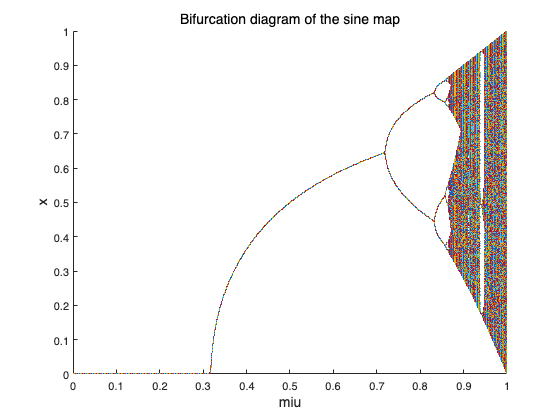

dmiu = 0.0001;
miu_min = 0;
miu_max = 1;
miu = miu_min:dmiu:miu_max;
nmiu = length(miu);
ncmax = 200;
tmax = 500;
x0 = 0.5;
figure;
clf;
hold on;
for i=1:nmiu
    u = miu(i);
    xt = miuIteration(tmax, x0, u);
    us = u * ones(1, ncmax);
    plot(us, xt(1, tmax- ncmax + 1: tmax), 'o', 'MarkerSize', 0.5);
end
ylabel('x', 'FontSize', 14);
xlabel('miu', 'FontSize', 14);
title('Bifurcation diagram of the sine map','FontSize',14)

﻿**Optional Exercise. **Take the renormalization group transformation we wrote down in class. How would you write a program to numerically compute the universal function? Think about the mapping as a transformation that take the function into another function. Perhaps you can start by writing subroutines to compute$x^* \left\lbrack g\right\rbrack$and $\alpha \left\lbrack g\right\rbrack$. Recall, the renormalization group equation from class:


$$T\left\lbrack g\right\rbrack \left(x\right)=\alpha \left\lbrack g\right\rbrack \left(g\left(g\left(\frac{x}{\alpha \left\lbrack g\right\rbrack }\right)+x^* \left\lbrack g\right\rbrack \right)-x^* \left\lbrack g\right\rbrack \right)$$


﻿Or it may be easier for you to use a different coordinate system, as we did in class:


$$T\left\lbrack g\right\rbrack \left(y\right)=\alpha \left\lbrack g\right\rbrack \left(g\left(g\left(\frac{y}{\alpha \left\lbrack g\right\rbrack }\right)\right)\right)$$


经推导，令$x=x-x_m$（$x_m$是$g\left(x\right)$的极大/小值点），则有：


$$g\left(x\right)=\alpha g^2 \left(\frac{x}{\alpha }\right)$$


从而有：

 
$$\alpha =\frac{g\left(0\right)}{g\left(g\left(0\right)\right)}$$


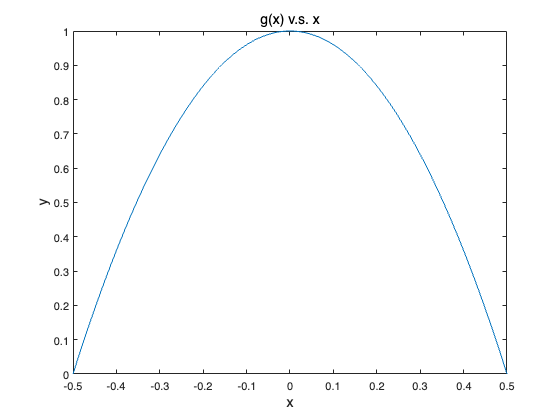

r = 4;
g_origin = @(x) r * x * (1 - x);
g = @(x) r * (x + 0.5) * (0.5 - x);
f = @(x) r * (x + 0.5) * (0.5 - x) - (x + 0.5);
% x_star_g = fzero(f, 0.2)
alpha = g(0) / g(g(0));
% T_g_x = @(x) alpha * (g(g(x / alpha)));
T_g_y = @(y) alpha * (g(g(y / alpha)));
xx = -0.5: 0.0001: 0.5;
yy = zeros(size(xx));
% T_xx = zeros(size(xx));
T_yy = zeros(size(xx));
length(xx);
for i = 1:length(xx)
%     T_xx(i) = T_g_x(xx(i));
    yy(i) = g(xx(i));
    T_yy(i) = T_g_y(yy(i));
end
figure;
plot(xx, yy);
ylabel('y', 'FontSize', 14);
xlabel('x', 'FontSize', 14);
title('g(x) v.s. x', 'FontSize', 14)

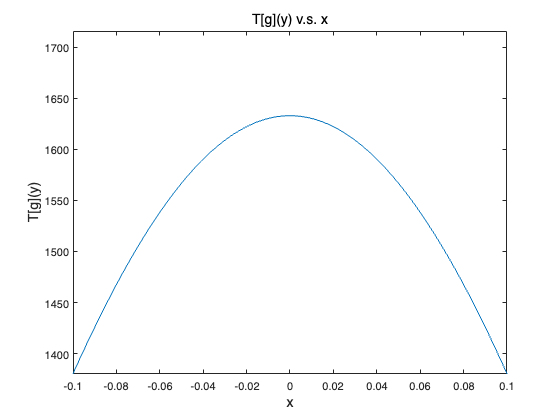


plot(xx, T_yy);
xlim([-0.1 0.1]);
ylim([1380 1716]);
ylabel('T[g](y)', 'FontSize', 14);
xlabel('x', 'FontSize', 14);
title('T[g](y) v.s. x', 'FontSize', 14)

### Function Complement

function xt = logisticIteration(tmax, x0, r)
    xt = zeros(1,tmax);
    xt(1,1) = x0;
    for i = 2: tmax
        xt(1,i) = r * (1-xt(1,i-1)) * xt(1,i-1);
    end
end

function xn1 = logisticFunc(xn, r) % vectorized
    xn1 = r * xn .* (1-xn);
end

function xt = miuIteration(tmax, x0, u)
    xt = zeros(1,tmax);
    xt(1,1) = x0;
    for i = 2: tmax
        xt(1,i) = u * sin(pi * xt(1, i - 1));
    end
end